# Train Multiple Agents for Longitudinal and Lateral Control

This example shows how to train multiple agents to collaboratively perform path-following control (PFC) for a vehicle. The goal of PFC is to make the ego vehicle travel at a set velocity while maintaining a safe distance from a lead car by controlling longitudinal acceleration and braking, and also while keeping the vehicle travelling along the centerline of its lane by controlling the front steering angle. For more information on PFC, see [Path Following Control System](docid:mpc_ref#mw_78ac0ef3-0622-4d5f-907b-52f6c7bebff6).

## Overview

An example that trains a reinforcement learning agent to perform PFC is shown in [Train DDPG Agent for Path Following Control](docid:rl_ug#mw_e40d4da8-366f-4eca-8e57-5b6f6a4f5093). In that example, a single deep deterministic policy gradient (DDPG) agent is trained to control both the longitudinal speed and lateral steering of the ego vehicle. In this example, you train two reinforcement learning agents — a DDPG agent provides continuous acceleration values for the longitudinal control loop and a deep Q-network (DQN) agent provides discrete steering angle values for the lateral control loop. 

The trained agents perform PFC through cooperative behavior and achieve satisfactory results.

## Create Environment

The environment for this example includes a simple bicycle model for the ego car and a simple longitudinal model for the lead car. The training goal is to make the ego car travel at a set velocity while maintaining a safe distance from lead car by controlling longitudinal acceleration and braking, while also keeping the ego car travelling along the centerline of its lane by controlling the front steering angle. 

Load the environment parameters.

clear all
close all
clc

rlAgentLCParams


## Set the sampling time nad total simulation times

Both agents operate at the same sample time in this example. Set the sample time value (in seconds).

Ts = 0.1;

%  set the simulation time
Tf = 15; % simulation time

## create the timeseries velocity vector

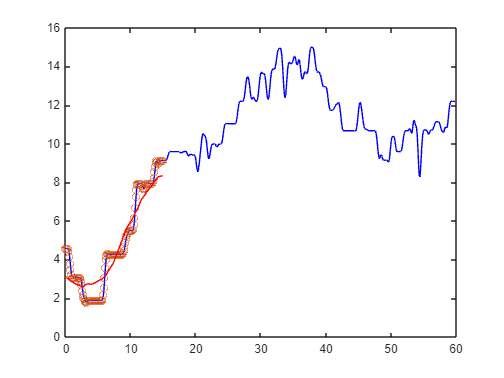

load('vehs.mat')
timeVec = 0:Ts:Tf-Ts;
timeVecOrg = 0:0.1:60-0.2; % the NGSIM data is for 59 sec
vSub = vehs(:,12);
% indx = ceil(linspace(1,length(vSub),Tf/Ts));
indx = timeVecOrg<=Tf;

vSubRed = vSub(indx);
vSubRedSmooth = smoothdata(vSubRed);
vSubRedSmooth = interp1(timeVecOrg(indx), vSubRedSmooth, timeVec);
plot(timeVecOrg, vSub', 'b')
hold on
plot(timeVecOrg(indx), vSubRed, 'O')
hold on
plot(timeVec, vSubRedSmooth, 'r')

vSubTimeSeries = timeseries(vSubRedSmooth, timeVec);


Open the Simulink model.

mdl = "rlAgentLCLatVaryingVxSUMO";
open_system(mdl)

Create the observation and action specifications for lateral control loop.

obsInfo1 = rlNumericSpec([4 1]);
actInfo1 = rlNumericSpec([1 1]);

Combine the observation and action specifications as a cell array.

obsInfo = obsInfo1;
actInfo = actInfo1;

Create a Simulink environment interface, specifying the block paths for both agent blocks. The order of the block paths must match the order of the observation and action specification cell arrays.

blks = mdl + ["/RL Agent1"];
env = rlSimulinkEnv(mdl,blks,obsInfo,actInfo);

Specify a reset function for the environment using the `ResetFcn` property. The function `pfcResetFcn` randomly sets the initial poses of the lead and ego vehicles at the beginning of every episode during training.

env.ResetFcn = @pfcResetFcn;

## Create Agents

For this example you create two reinforcement learning agents. First, fix the random seed for reproducibility.

rng(0)

### Lateral Control

agent1 = createLatAgentPinWangOrg(obsInfo1, actInfo1,Ts);

## Train Agents

Specify the training options. For this example, use the following options.

- Run each training episode for at most 5000 episodes, with each episode lasting at most `maxsteps` time steps.

- Display the training progress in the Episode Manager dialog box (set the `Verbose` and `Plots` options).

- Stop training the DDPG and DQN agents when they receive an average reward greater than 480 and 1195, respectively. When one agent reaches its stop criteria, it simulates its own policy without learning while the other agent continues training.

trainOpts = rlTrainingOptions(...
    MaxEpisodes=5000, ...
    MaxStepsPerEpisode=ceil(Tf/Ts), ...
    Verbose=false, ...
    Plots="training-progress",...
    StopTrainingCriteria="AverageReward",...
    StopTrainingValue=1,...
    UseParallel = false);

Train the agents using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training these agents is a computationally intensive process that takes several minutes to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

doTraining = true;
if doTraining    
    % Train the agent.
    trainingStats = train(agent1,env,trainOpts);
else
    % Load pretrained agents for the example.
    load("DDPGTrain5PingWangOrg.mat")       
end

The following figure shows a snapshot of the training progress for the two agents.

## Simulate Agents

To validate the performance of the trained agents, simulate the agents within the Simulink environment by uncommenting the following commands. For more information on agent simulation, see [`rlSimulationOptions`](docid:rl_ref#mw_983bb2e9-0115-4548-8daa-687037e090b2) and [`sim`](docid:rl_ref#mw_e6296379-23b5-4819-a13b-210681e153bf).

simOptions = rlSimulationOptions(MaxSteps=ceil(Tf/Ts));
experience = sim(env, agent1, simOptions);

To demonstrate the trained agent using deterministic initial conditions, simulate the model in Simulink.

% e1_initial = -0.4;
% e2_initial = 0.1;
% x0_lead = 80;
% sim(mdl)

The following plots show the results when the lead car is 70 m ahead of the ego car at the beginning of simulation. 

- The lead car changes speed from 24 m/s to 30 m/s periodically (top-right plot). The ego car maintains a safe distance throughout the simulation (bottom-right plot). 

- From 0 to 30 seconds, the ego car tracks the set velocity (top-right plot) and experiences some acceleration (top-left plot). After that, the acceleration is reduced to 0.

- The bottom-left plot shows the lateral deviation. As shown in the plot, the lateral deviation is greatly decreased within 1 second. The lateral deviation remains less than 0.1 m. 

*Copyright 2020 The MathWorks, Inc.*